Load the Test Data

file_path = "mnist.mat";
load(file_path);

Creat confusion Matrix

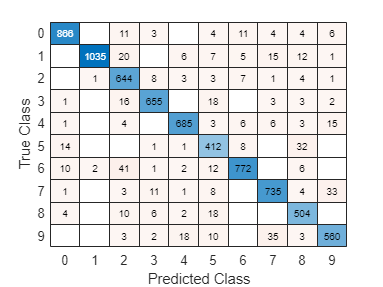

size_K = 10;
confusion_matrix = zeros(size_K,size_K);

for i=0:(size_K-1)
    for j=0:(size_K-1)
        confusion_matrix(i+1,j+1) = ova_classifier(i,j);
    end
end

%imagesc(confusion_matrix);
%imshow(confusion_matrix);

confusionchart(confusion_matrix, 0:9)

Define the function

function value = ova_classifier(i,j)
file_path = "mnist.mat";
load(file_path);
% trainX and testX need to be normalized and converted to type double
% ./ is element wise division
trainX_normalized=double(trainX);
trainX_normalized= trainX_normalized./255; 
testX_normalized=double(testX);
testX_normalized=testX_normalized./255;

%trainY and testY need to only be converted to type double
trainY= double(trainY);
testY= double(testY);

%operation will be completed from 1 to N where N is the length of x_i
%Should be 60,000
N=size(trainX_normalized,1);
%operaton will consider 10 classes 0-9. K will be number i
K=i;


% solve min ( y - Av)
% where y is the result, A is our input data, and x is unknown
% therefore we want to compute v = inv(A)*y

%add our columns of 1s for linear regression
X=[trainX_normalized, ones(N,1)];

y= trainY;


% set our sign values, we want to train so that the output of 
% number K is 1 and the output of not k is -1
y( y~=K ) = -1;
y( y==K ) = 1;


%We use pinv to find the orthogonal vector to the basis so that 
% the min || y-z || is closest to 0
v=pinv(X)*y';

%test model on the data
test_data_y = testY;


%Set proper sign values for result of y
test_data_y( test_data_y ~= K ) = -1;
test_data_y( test_data_y == K ) = 1;


test_data_y=test_data_y';

N_2 = size(testX_normalized,1);
test_X = [testX_normalized, ones(N_2,1)];

%Multiply our solved for v matrix to the input test data
result_test = sign(test_X * v);

indexes= find(testY == j);

if (i == j)
    value = sum(result_test(indexes) == test_data_y(indexes));
else
    value = sum(result_test(indexes) ~= test_data_y(indexes));
end
%disp(value)
end